## Get Signal

clear;
close all

if ispc
    addpath('..\..\audio_files');
    addpath('..\..\sim_environment');
else
    addpath('../../audio_files');
    addpath('../../sim_environment');
end
fs_RIR = 8000; 
siglength = 10;
sig = get_audio_sig('speech1.wav',fs_RIR,siglength);

## WOLA analysis TEST

nfft = 1024;
overlap = 2;
window = dsp.Window( ...
    'WindowFunction','Hanning', ...
    'WeightsOutputPort',true);
% -------choose speech signal or random signal----

x_wola = sig;
%x_wola = randn(10000,1);

[X_ana,vector] = WOLA_analysis(x_wola,fs_RIR,window,nfft,overlap);


## WOLA synthesis TEST 

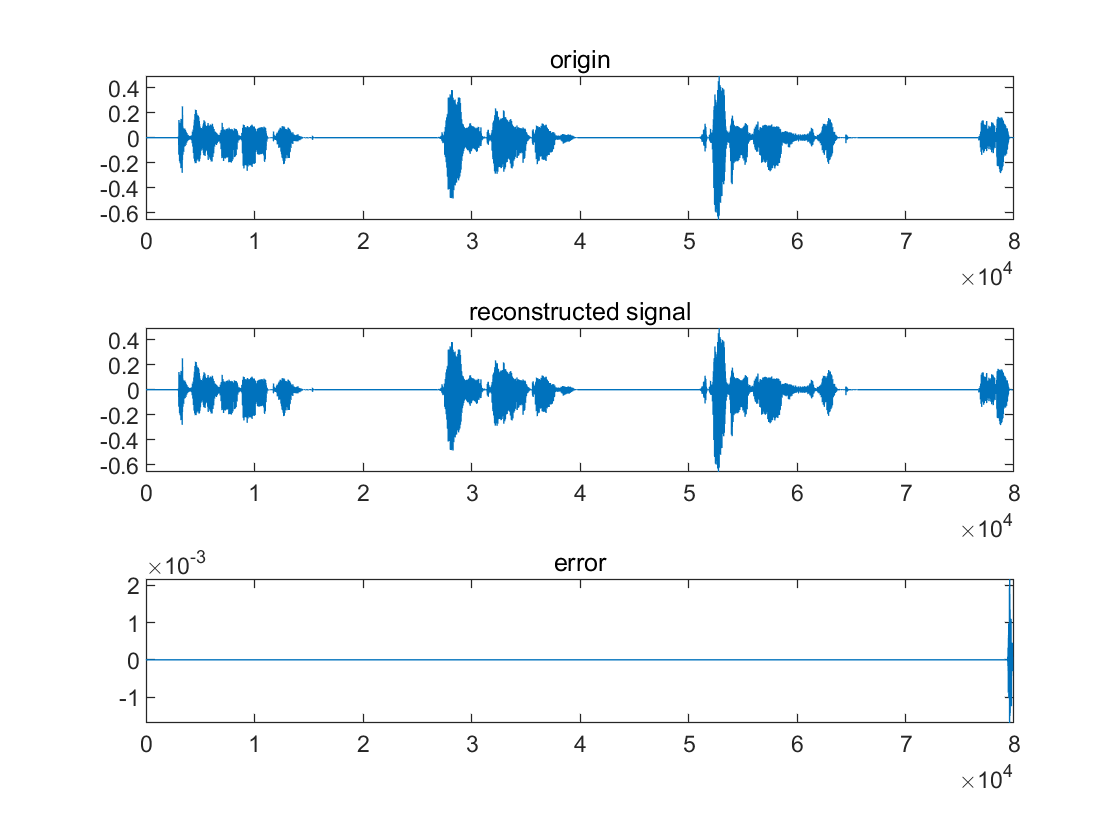

% overlap = 0.5;
x_syn = WOLA_synthesis(X_ana,window,nfft,overlap);

figure(1)

subplot(3,1,1)
plot(x_wola(:,1))
title("origin")
subplot(3,1,2)
plot(x_syn(:,1))
title("reconstructed signal")
subplot(3,1,3)
len = min(length(x_wola),length(x_syn));
plot(x_wola(1:len,1) - x_syn(1:len,1));
title("error")

% Here you will see the 'edge effect' both at front and end. It's because
% there is no 'overlap signal' to complement the loss of information.

## Spectrogram

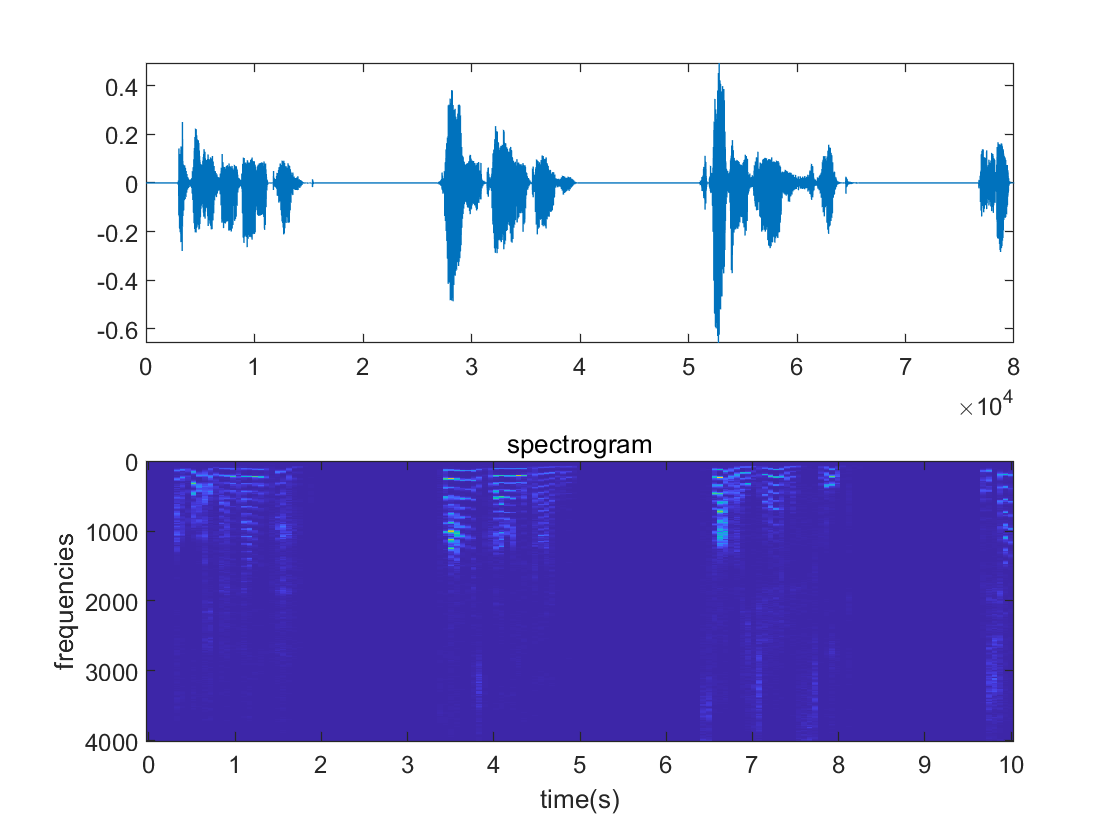

figure;
subplot(2,1,1)
plot(x_wola(:,1))
subplot(2,1,2);
colormap default
time_vector = 0:siglength/size(X_ana,2):siglength;
imagesc(time_vector,vector,abs(X_ana));
title('spectrogram')
xlabel('time(s)')
ylabel('frequencies')